%modified based on https://www.mathworks.com/help/supportpkg/xilinxzynqbasedradio/ug/receive-tone-signal-using-analog-devices-ad9361-ad9364.html

tx=sdrtx('Pluto','RadioID','ip:192.168.1.10')

tx =   comm.SDRTxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'ip:192.168.1.10'
           CenterFrequency: 2.4000e+09
                      Gain: -10
            ChannelMapping: 1
        BasebandSampleRate: 1000000
    ShowAdvancedProperties: false

  Show all properties


tx.RadioID

ans = 'ip:192.168.1.10'

tx.AD9361MaxSampRate

ans = 61440000

tx.Gain

ans = -10

tx.GainSource

ans = 'Dialog'

tx.BasebandSampleRate

ans = 1000000

tx.ChannelMapping

ans = 1

tx.CenterFrequency

ans = 2.4000e+09

tx.filtRFBandwidth

ans = 18000000

tx.ShowAdvancedProperties

ans = logical
   0



RadioBasebandRate = 1e6;
CenterFrequency = 2.4e9;
ToneFrequency = 25e3; %25KHz

tx.BasebandSampleRate = RadioBasebandRate;
tx.CenterFrequency = CenterFrequency;
tx.ShowAdvancedProperties = true

tx =   comm.SDRTxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'ip:192.168.1.10'
           CenterFrequency: 2.4000e+09
                      Gain: -10
            ChannelMapping: 1
        BasebandSampleRate: 1000000
    ShowAdvancedProperties: true

  Show all properties


tx.DataSourceSelect = 'DDS';
tx.DDSTone1Scale = 0.1;
tx.DDSTone2Scale = 0.1;
tx.DDSTone1Freq = ToneFrequency;
tx.DDSTone2Freq = ToneFrequency;
tx.Gain = 0;

tx()

## Establishing connection to hardware. This process can take several seconds.


ans = logical
   0



% Radio parameters
RadioFrameLength = 4000;

% Create a receiver System object with desired radio parameters
rx = sdrrx('Pluto','RadioID','ip:192.168.1.10')

rx =   comm.SDRRxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'ip:192.168.1.10'
           CenterFrequency: 2.4000e+09
                GainSource: 'AGC Slow Attack'
            ChannelMapping: 1
        BasebandSampleRate: 1000000
            OutputDataType: 'int16'
           SamplesPerFrame: 20000
           EnableBurstMode: false
    ShowAdvancedProperties: false

  Show all properties


rx.RadioID

ans = 'ip:192.168.1.10'

rx.AD9361MaxSampRate

ans = 61440000

rx.OutputDataType

ans = 'int16'

rx.SamplesPerFrame

ans = 20000

rx.SampleTime

ans = 0.0200

rx.Gain

ans = 10

rx.GainSource

ans = 'AGC Slow Attack'

rx.BasebandSampleRate

ans = 1000000

rx.ChannelMapping

ans = 1

rx.CenterFrequency

ans = 2.4000e+09

rx.filtRFBandwidth

ans = 18000000


rx.BasebandSampleRate = RadioBasebandRate;
rx.CenterFrequency = CenterFrequency;
rx.ChannelMapping = 1

rx =   comm.SDRRxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'ip:192.168.1.10'
           CenterFrequency: 2.4000e+09
                GainSource: 'AGC Slow Attack'
            ChannelMapping: 1
        BasebandSampleRate: 1000000
            OutputDataType: 'int16'
           SamplesPerFrame: 20000
           EnableBurstMode: false
    ShowAdvancedProperties: false

  Show all properties


rx.OutputDataType = 'double';
rx.GainSource = 'AGC Fast Attack'; %'Manual';
rx.ShowAdvancedProperties = true

rx =   comm.SDRRxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'ip:192.168.1.10'
           CenterFrequency: 2.4000e+09
                GainSource: 'AGC Fast Attack'
            ChannelMapping: 1
        BasebandSampleRate: 1000000
            OutputDataType: 'double'
           SamplesPerFrame: 20000
           EnableBurstMode: false
    ShowAdvancedProperties: true

  Show all properties


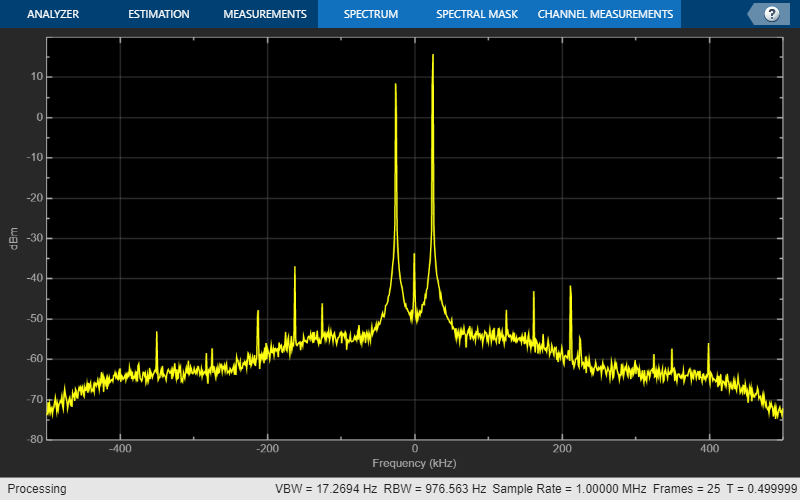

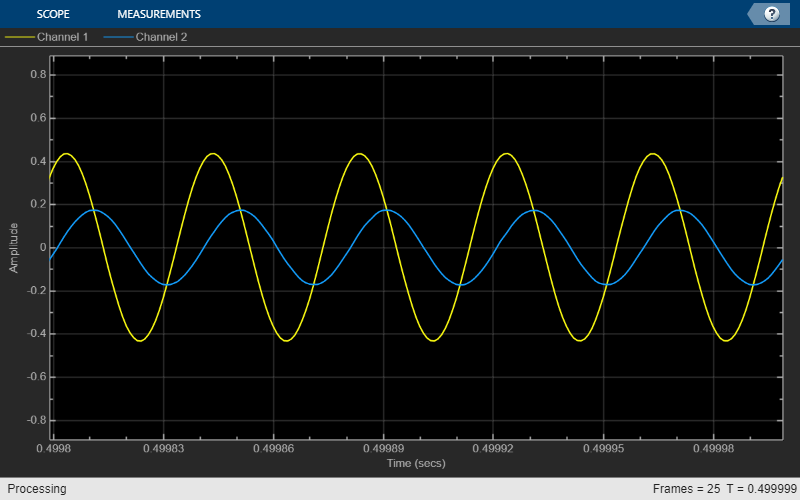

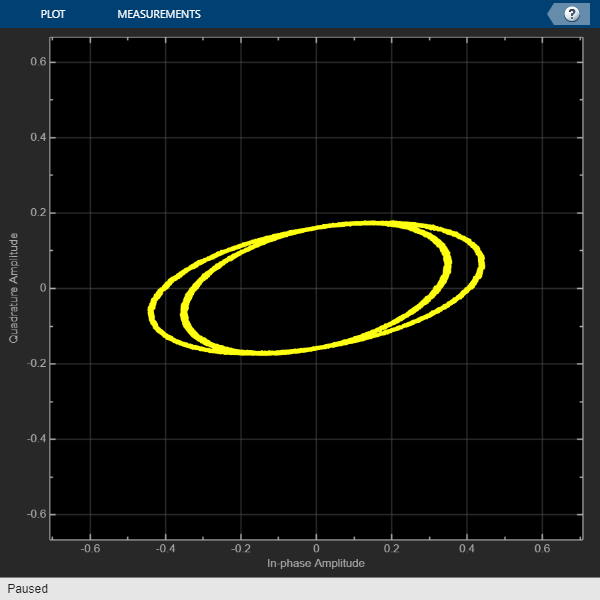

## Establishing connection to hardware. This process can take several seconds.


%BypassUserLogic



spectrumScope = spectrumAnalyzer('SampleRate', RadioBasebandRate);
timeScope = timescope('TimeSpanSource','property','TimeSpan',5/ToneFrequency,'SampleRate',RadioBasebandRate);
constellation = comm.ConstellationDiagram('ShowReferenceConstellation', false);

StopTime        = 100e-3;                                 % seconds
RadioFrameTime  = (RadioFrameLength / RadioBasebandRate); % seconds

numFramesinBurst = ceil(RadioBasebandRate*StopTime/RadioFrameLength);
rx.EnableBurstMode = true;
rx.NumFramesInBurst = numFramesinBurst;

try
    % Loop until the example reaches the target stop time.
    timeCounter = 0;
    
    while timeCounter < StopTime
        
        [data, valid, overflow] = rx();
        if (overflow > 0) && (timeCounter > 0)
            disp("Dropped samples");
        end
        
        if valid
            % Visualize frequency spectrum
            spectrumScope(data);
            % Visualize in time domain
            timeScope([real(data), imag(data)]);
            % Visualize the scatter plot
            constellation(data);
            
            % Set the limits in scopes
            dataMaxLimit = max(abs([real(data); imag(data)]));
            constellation.XLimits = [-dataMaxLimit*1.5, dataMaxLimit*1.5];
            constellation.YLimits = [-dataMaxLimit*1.5, dataMaxLimit*1.5];
            timeScope.YLimits = [-dataMaxLimit*2, dataMaxLimit*2];
            timeCounter = timeCounter + RadioFrameTime;
        end
    end
catch ME
    rethrow(ME);
end


release(rx);
release(tx);
